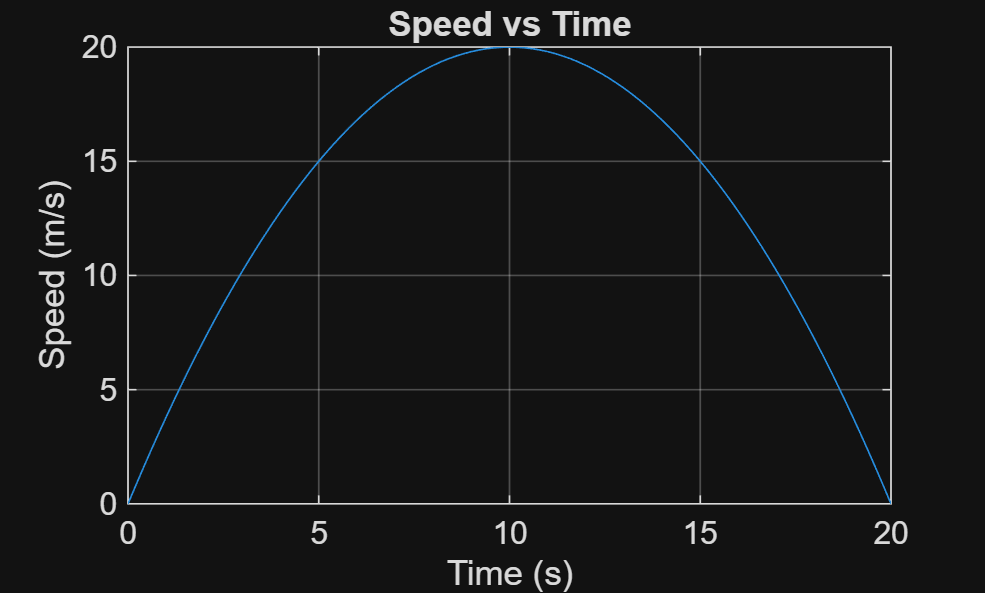

t = 0:0.2:20;                 % time vector
v = -0.2*(t - 10).^2 + 20;   % speed function

figure;
plot(t, v)
xlabel('Time (s)')
ylabel('Speed (m/s)')
title('Speed vs Time')
grid on

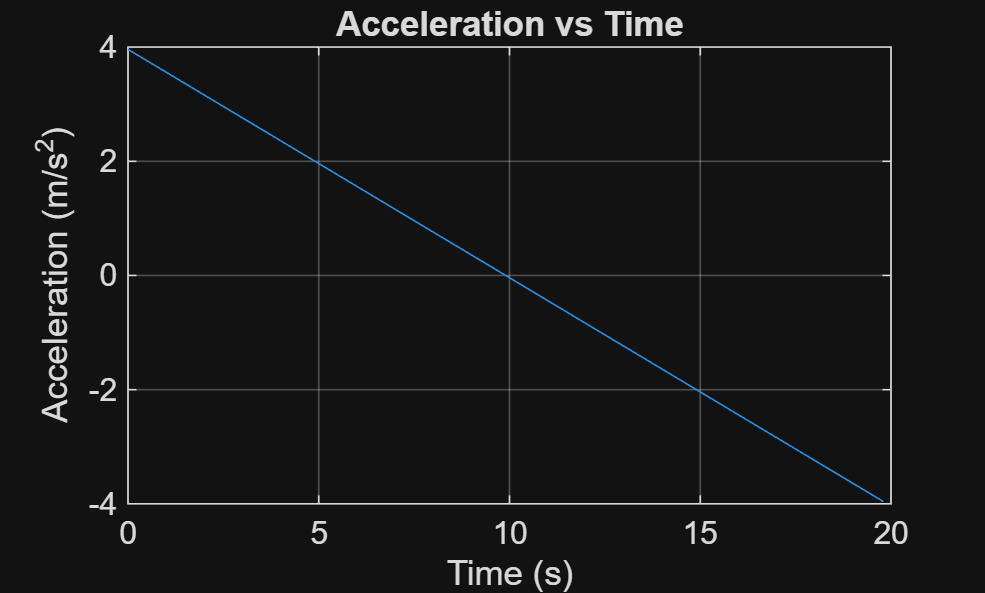


dt = 0.2;
a = diff(v) / dt;     % numerical derivative
t_a = t(1:end-1);     % match time vector length

figure;
plot(t_a, a)
xlabel('Time (s)')
ylabel('Acceleration (m/s^2)')
title('Acceleration vs Time')
grid on


[max_v, idx] = max(v);
t_max = t(idx);

disp(['Maximum speed occurs at t = ', num2str(t_max), ' s'])

Maximum speed occurs at t = 10 s
